clc,clear

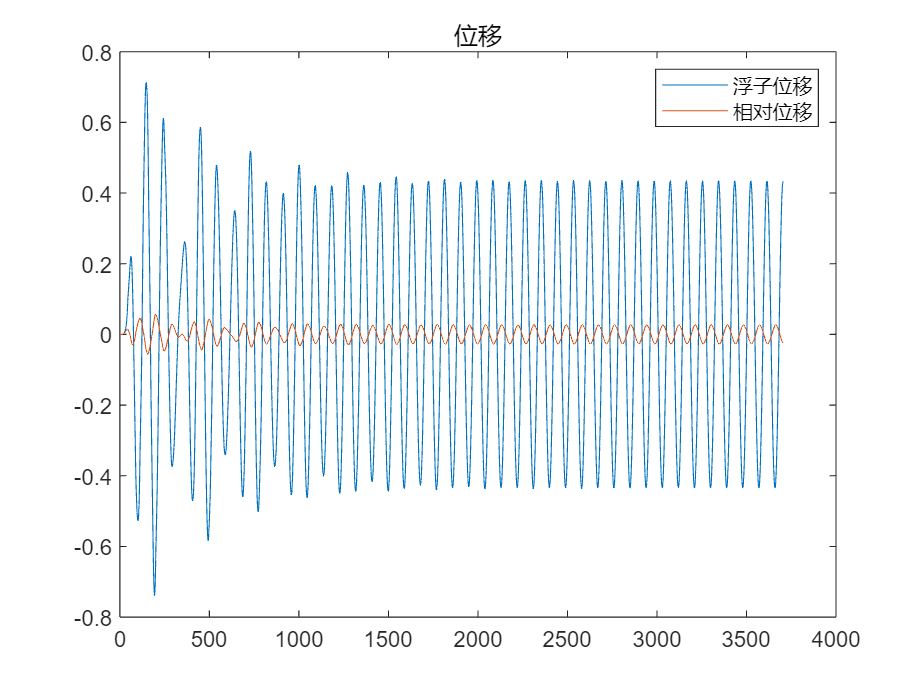

%initialize parameter
g=9.8;                                   %重力加速度 (m/s2)      
dt=0.2;                                  %步长设为0.2s
w=1.4005;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）
T=2*pi/w;
T_end=40*T;                              %总数值模拟时间(s) 
%%初值设置               
v1=0;                                    %浮子的初始速度 (m/s)
v2=0;                                    %振子的初始速度 (m/s)
x_f=0;                                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
x_v=0;                                   %振子的初始位移 (m)
X0=[x_f;x_v;v1;v2];
tspan=[0,T_end];
options = odeset('MaxStep', dt);         % 设置最大步长为 0.1
[~, X] = ode45(@S_diff_equ, tspan, X0, options);
X=X';
plot(X(1,:))
title('位移')
hold on 
x=X(1,:)-X(2,:);
plot(x)
legend('浮子位移','相对位移')
hold off

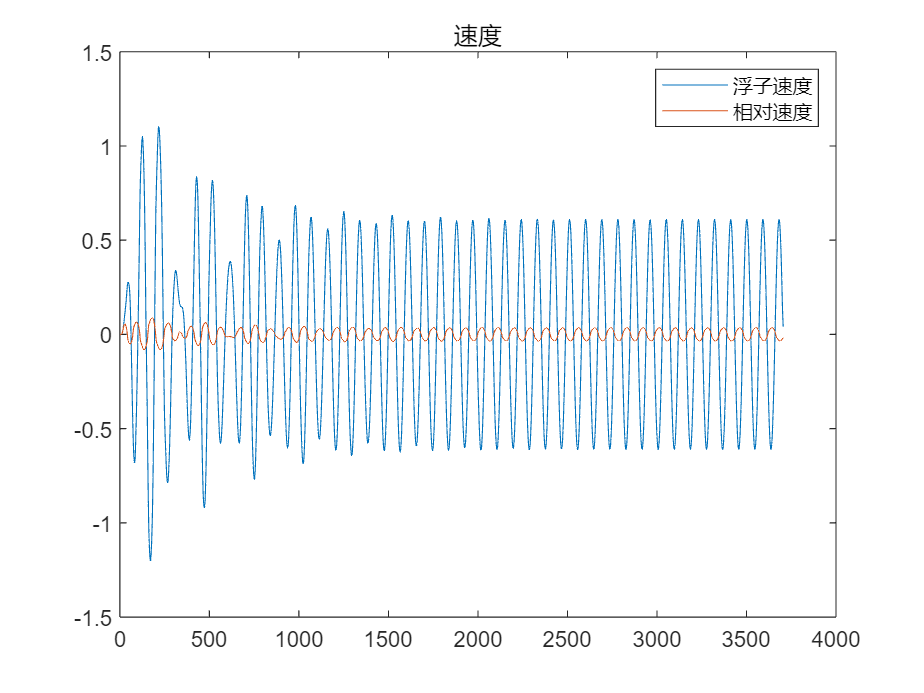

plot(X(3,:))
title('速度')
hold on
plot(X(3,:)-X(4,:))
legend('浮子速度','相对速度')
hold off



t=0:size(X,2)-1;
t=t*0.2;
t=t';
X=X';
X(:,[2,3])=X(:,[3,2]);
X=[t,X];
filename = 'result1-2.xlsx';
data_table = array2table(X);
data = [1, 2, 3; 4, 5, 6; 7, 8, 9];
sheet = 'Sheet1'; % 指定要写入的Sheet名称
xlRange = 'A3';   % 指定写入范围的起始单元格
writetable(data_table, filename, 'Sheet', sheet, 'Range', xlRange);
index1=find(abs(t-10)==min(abs(t-10)),1);
index2=find(abs(t-20)==min(abs(t-20)),1);
index3=find(abs(t-30)==min(abs(t-30)),1);
index4=find(abs(t-40)==min(abs(t-40)),1);
index5=find(abs(t-50)==min(abs(t-50)),1);
fprintf('时间 (s)\t浮子\t\t  振子 \n\t\t位移 \t速度 \t  位移 \t     速度 ')

时间 (s)	浮子		  振子 
		位移 	速度 	  位移 	     速度 

disp(X(index1,:))

   10.0000    0.1490    0.2637    0.1424    0.3083



disp(X(index2,:))

   20.0000   -0.5265    0.0129   -0.5587   -0.0416



disp(X(index3,:))

   30.0000    0.6901   -0.2917    0.7413   -0.2498



disp(X(index4,:))

   40.0000   -0.6051    0.6680   -0.6609    0.6889



disp(X(index5,:))

   50.0000    0.5169   -0.4881    0.5611   -0.5196



% function delta_f=ca_f_float(rho,g,x,V0,V_max,r_cost,h)  
%     if x<=-h
%         delta_V=V0-V_max;
%     elseif x<=3-h&&x>-h
%         delta_V=-x*h*pi*r_cost^2; 
%     elseif x<=3.8-h&&x>3-h
%         delta_V=-pi*r_cost^2*(3-h)-1/3*pi*((3.8-x)/0.8)^2*(3.8-x);
%     else 
%         delta_V=-V0;
%     end
%     delta_f=rho*g*delta_V;
% end

function dxdt=S_diff_equ(t,X)
    k=1e+5;
    %initialize parameter
    m1=4866;                                 %浮子质量 (kg)
    r_f=1;                                   %浮子底半径 (m)
    h_cast=3;                                %浮子圆柱部分高度 (m)
    h_cone=0.8;                              %浮子圆锥部分高度 (m)
    V_cast=pi*r_f^2*h_cast;                  %圆柱体积 (m3)
    V_cone=1/3*h_cone*pi*r_f^2;              %圆锥体积(m3)
    V_max=V_cone+V_cast;                     %浮子体积
    m2=2433;                                 %振子质量 (kg)
    m_add=1335.535;                          %垂荡附加质量 (kg)
    g=9.8;                                   %重力加速度 (m/s2)
    G1=m1*g;                                 %浮子重力  (N)
    G2=m2*g;                                 %振子重力  (N)
    rho=1025;                                %海水的密度 (kg/m3)
    ke=80000;                                %弹簧刚度 (N/m)
    w=1.4005;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                 
    kr=656.3616;                             %垂荡兴波阻尼系数 (N·s/m)
    f_max=6250;                              %垂荡激励力振幅 (N)
    V0=V_max-(G1+G2-f_max)/(rho*g);          %初始沉入水中体积(m3)
    r_cost=1;                                %浮子底半径 (m)
    %h=(V_max-(m1*g+m2*g-f_max)/(rho*g))/pi;  %水面的高度(m)
    h=(V_max-(m1*g+m2*g)/(rho*g))/pi;  %水面的高度(m)
    dxdt=zeros(4,1);
    k=k*sqrt(abs(X(3)-X(4)));
    dxdt(1)=X(3);
    dxdt(2)=X(4);
    dxdt(3)=(-k*(X(3)-X(4))-ke*(X(1)-X(2))+f_max*cos(w*t)-kr*X(3)-rho*g*pi*r_cost^2*X(1))/(m1+m_add);
    dxdt(4)=(k*(X(3)-X(4))+ke*(X(1)-X(2)))/m2;
end